# Showcasing current DMD class capabilities

#### Data preparation

load("..\data\imgV2.mat");
perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');
fs = 50; %Hz

% Organize the data into "snapshots": spatial is rows, time is columns
% Restrict data window
xStart = 1000;
xEnd = 1500;

stdMap = std(imgV2,[],3);
imgFilt = imgV2 .* repmat(stdMap > max(stdMap(:)) * 0.5, 1, 1, size(imgV2, 3));
flatImg = reshape(imgFilt(:,:,xStart:xEnd),32*32,[]);
X = flatImg(:,1:end-2);
Y = flatImg(:,2:end-1);

t = (0:(size(flatImg,2)-1))'/fs;

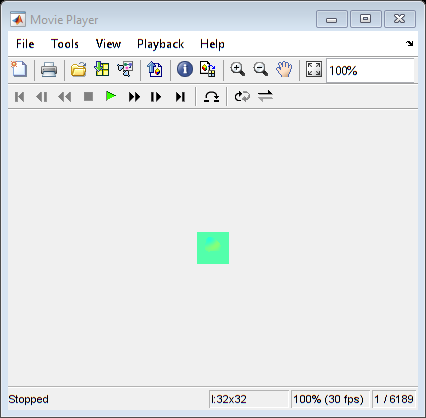

% Select heart and lung pixels
img = imgV2(:,:,xStart:xEnd);

heartPix = [7,15];
lungPix = [14,22];

heartSig = squeeze(img(heartPix(1),heartPix(2),:));
lungSig = squeeze(img(lungPix(1),lungPix(2),:));

% Preview of what the real data looks like
playVideo(imgFilt);

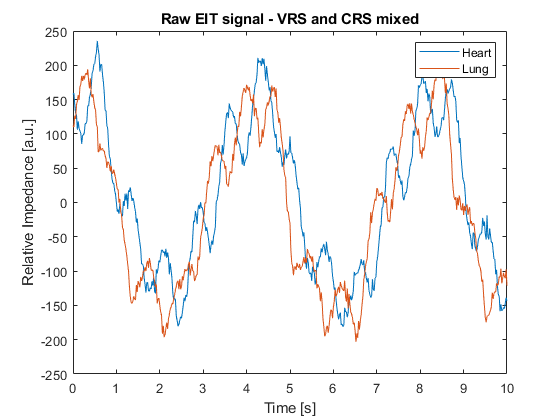

figure; plot(t, [heartSig,lungSig]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
title("Raw EIT signal - VRS and CRS mixed");

#### Simple DMD

% Initialize DMD class and properties
dmd = DMD();
rank = 32; % rank to truncate data to
predHor = 100; % prediction horizon (in samples)
tSim = (1:predHor)'/fs + t(end);

% Modified Exact DMD
tic
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, X, Y, rank, predHor);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, X, Y, fs, 'exact-mod');
[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
toc

Elapsed time is 0.072902 seconds.


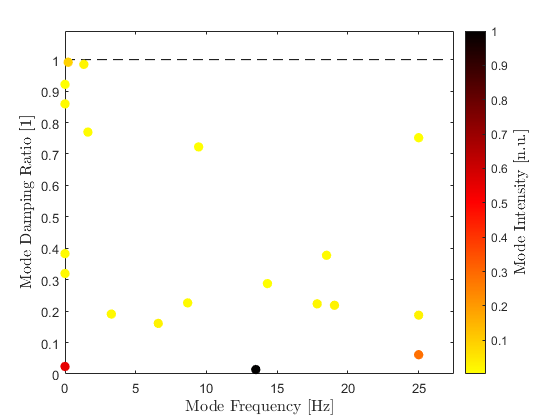

ans = 1


% Visualization
damFreq(dmd, norms, mags, freqs);1

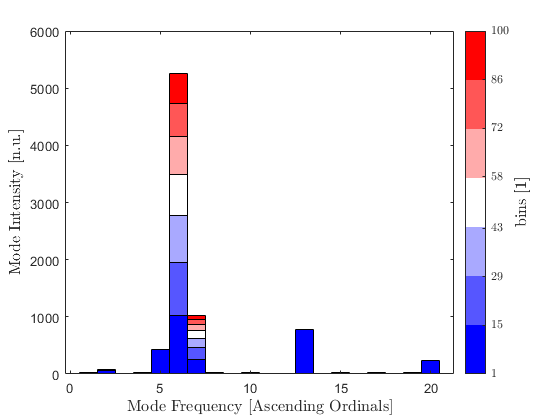

domStruct(dmd, freqs, lambda, Phi, b, predHor);

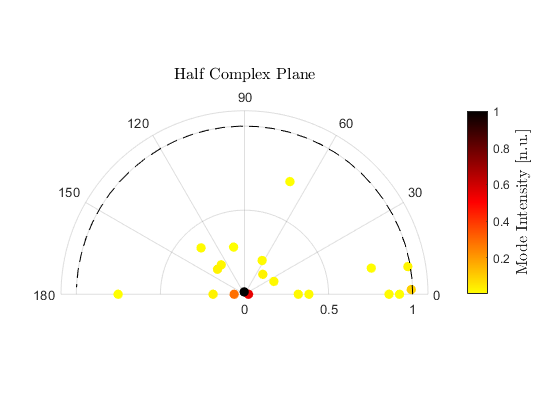

nyqPlot(dmd, norms, freqs, mags, lambda);

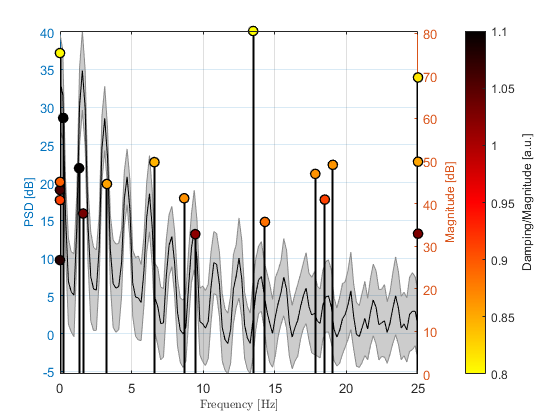

powSpect(dmd, X, freqs, norms, mags, fs);

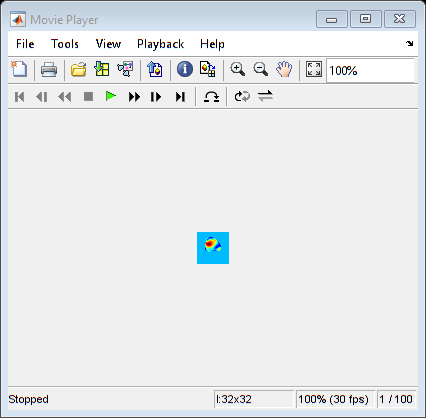

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),32,32,[]));

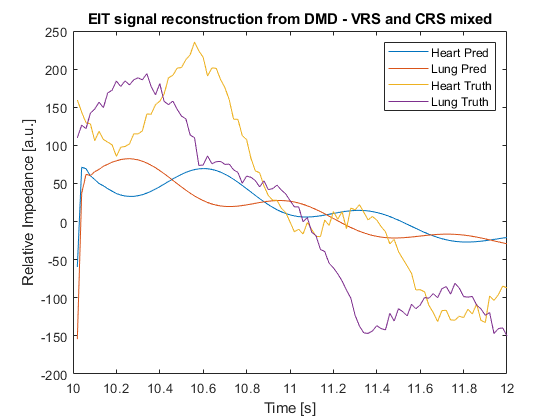

img = real(reshape(Xtotal,32,32,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Filter DMD Modes

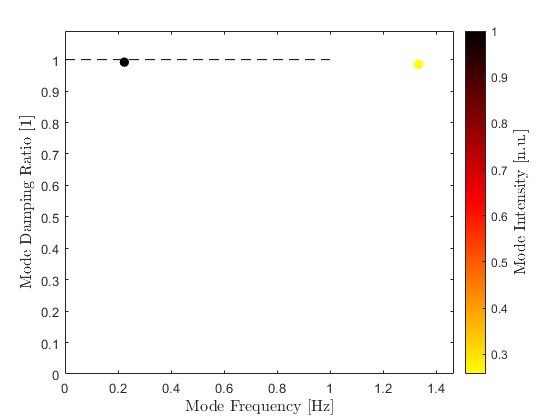

ans = 1

freqLims = [0.1,10];
damLims = [0.9,1.1];
magLims = [0, 1];

[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, lambda, omega, Phi, b, magLims, damLims, freqLims);

% Visualization
damFreq(dmd, norms, mags, freqs);1

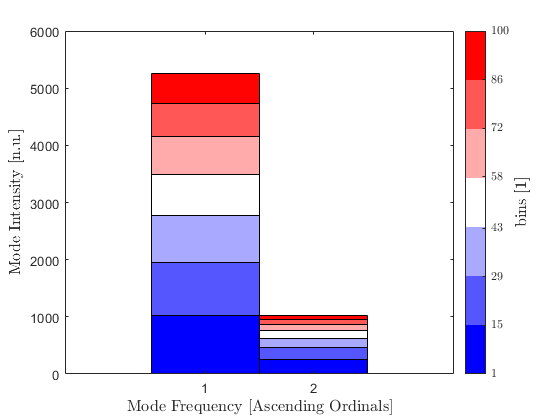

domStruct(dmd, freqs, lambda, Phi, b, predHor);

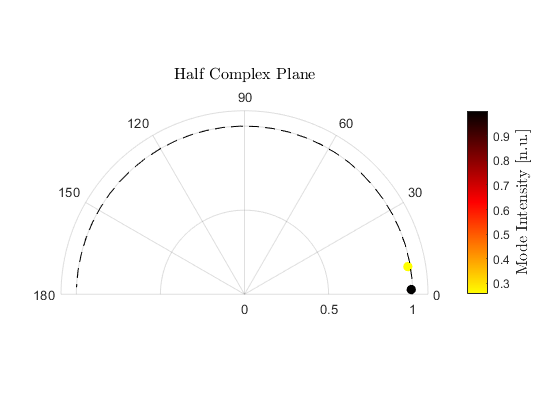

nyqPlot(dmd, norms, freqs, mags, lambda);

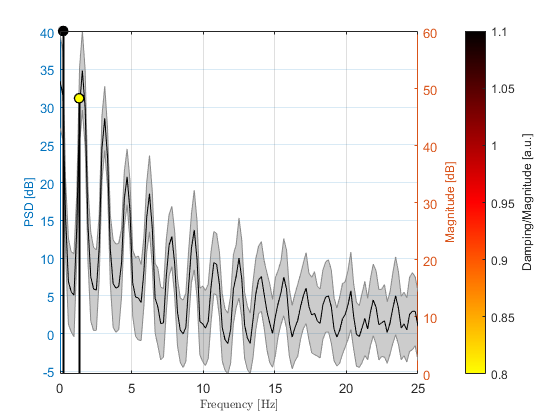

powSpect(dmd, X, freqs, norms, mags, fs);

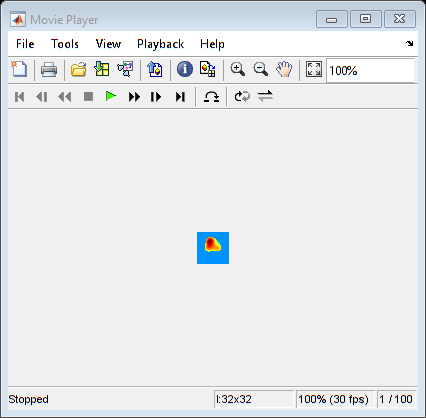

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),32,32,[]));

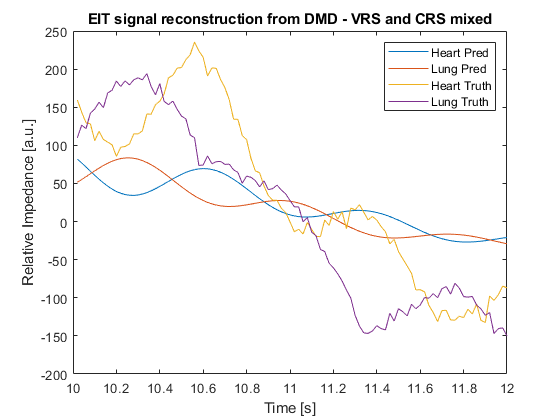

img = real(reshape(Xtotal,32,32,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Compressed Sensing DMD - get good results more than twice as fast

% Compressed Modified Exact DMD
m = 128; % number of pixels to consider
projType = 2;

tic
[cX, cY, C] = compressData(dmd, X, Y, m, projType);
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, cX, cY, rank, predHor);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, cX, cY, fs, 'exact-mod', X, Y);
[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
toc

Elapsed time is 0.057082 seconds.


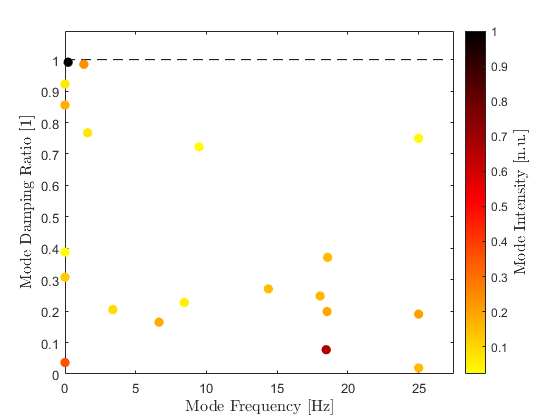


% Visualization
damFreq(dmd, norms, mags, freqs);

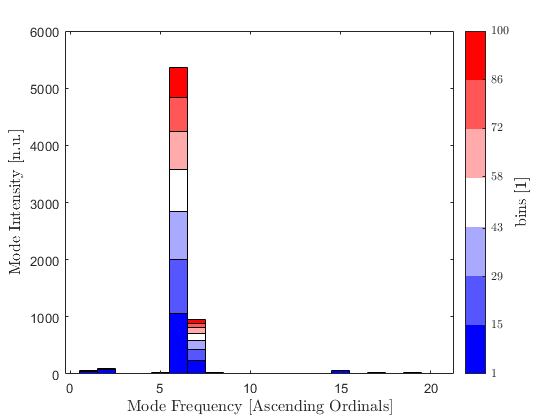

domStruct(dmd, freqs, lambda, Phi, b, predHor);

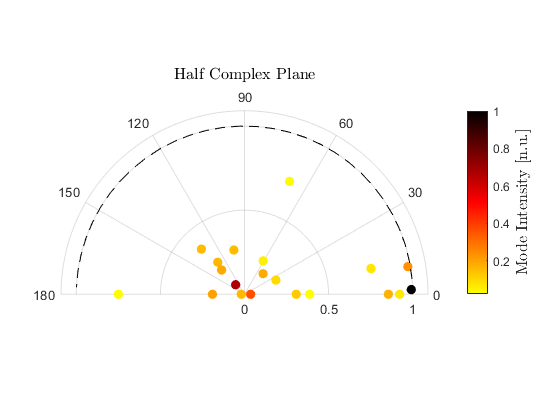

nyqPlot(dmd, norms, freqs, mags, lambda);

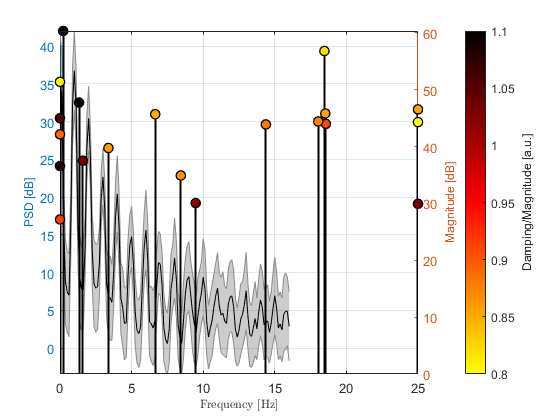

powSpect(dmd, X, freqs, norms, mags, rank);

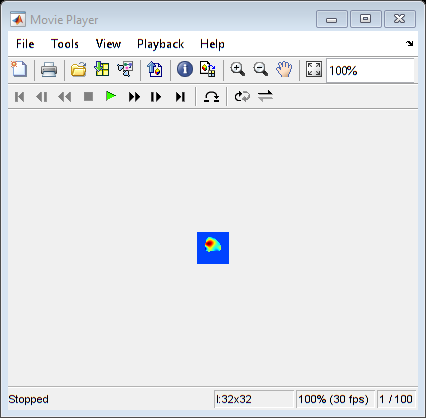

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),32,32,[]));

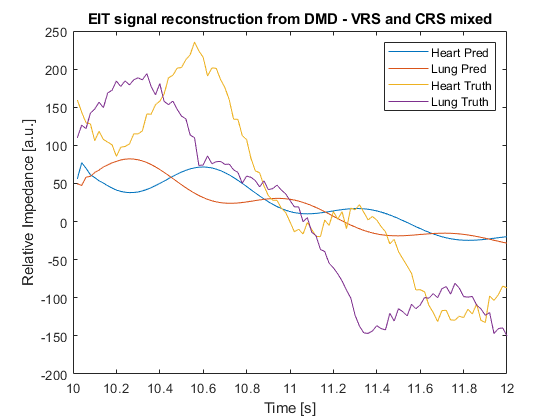

img = real(reshape(Xtotal,32,32,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Filter DMD Modes

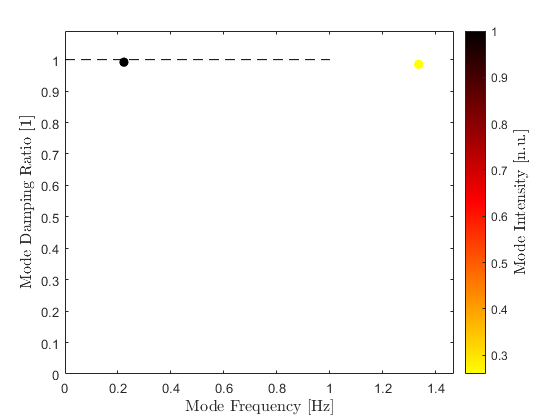

freqLims = [0.1,10];
damLims = [0.9,1.1];
magLims = [0, 1];

[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, lambda, omega, Phi, b, magLims, damLims, freqLims);

% Visualization
damFreq(dmd, norms, mags, freqs);

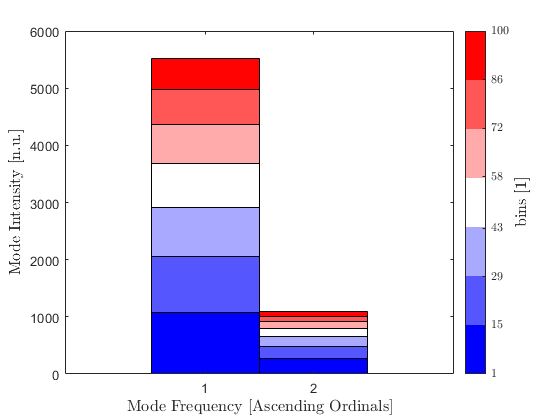

domStruct(dmd, freqs, lambda, Phi, b, predHor);

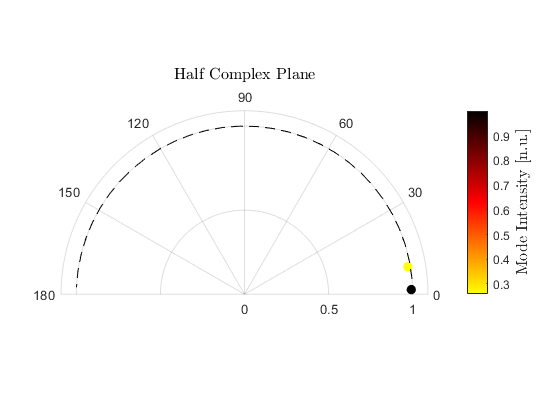

nyqPlot(dmd, norms, freqs, mags, lambda);

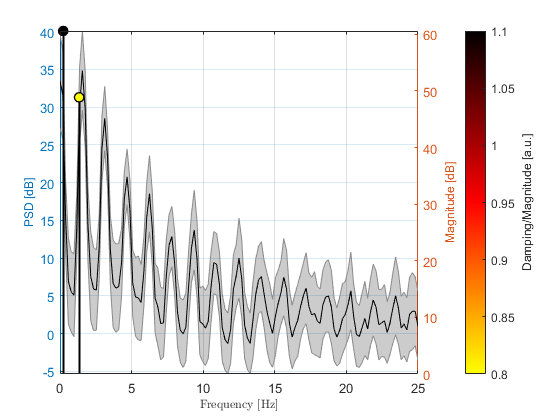

powSpect(dmd, X, freqs, norms, mags, fs);

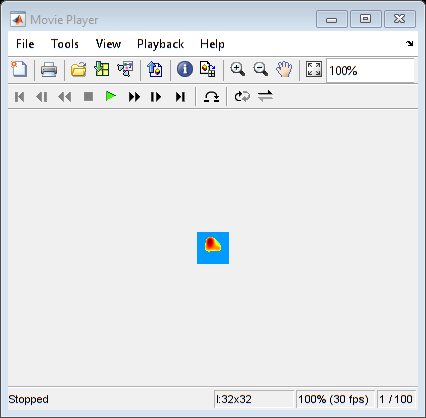

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),32,32,[]));

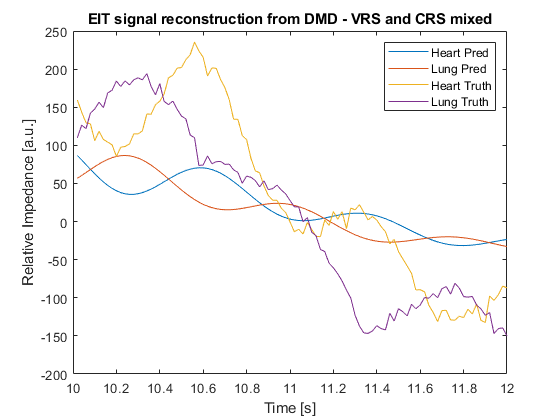

img = real(reshape(Xtotal,32,32,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Multi-Resolution DMD (has filtering incorporated)

% Compressed Multi-Resolution DMD
% Set desired ranges for frequency, norm (or damping factor), and magnitude
nLevels = 5;
freqLims = [0.1,10];
damLims = [0.9,1];
magLims = [0, 1];

tic
[lambda, omega, Phi, b] = mrFit(dmd, X, Y, rank, nLevels, predHor);

[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                                                    lambda, omega, Phi, b, ....
                                                                                    magLims, damLims, freqLims);

toc

Elapsed time is 0.162552 seconds.


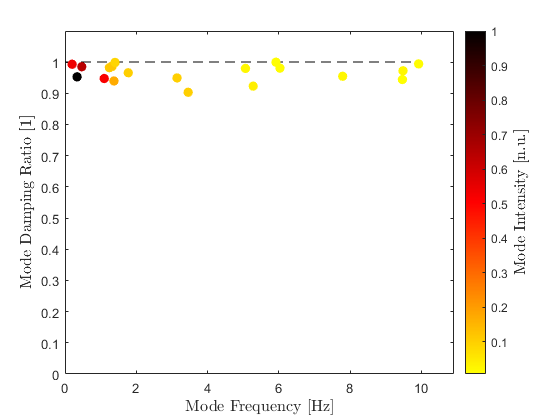

% Visualization
damFreq(dmd, norms, mags, freqs);

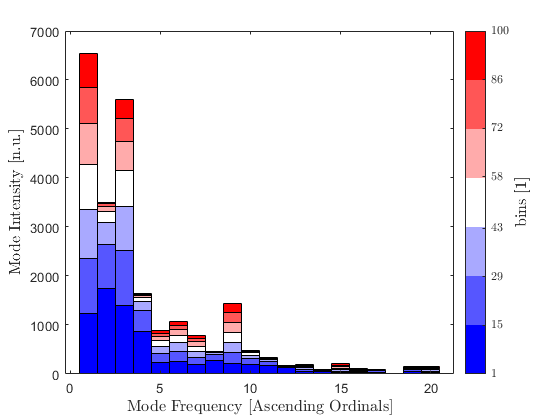

domStruct(dmd, freqs, lambda, Phi, b, predHor);

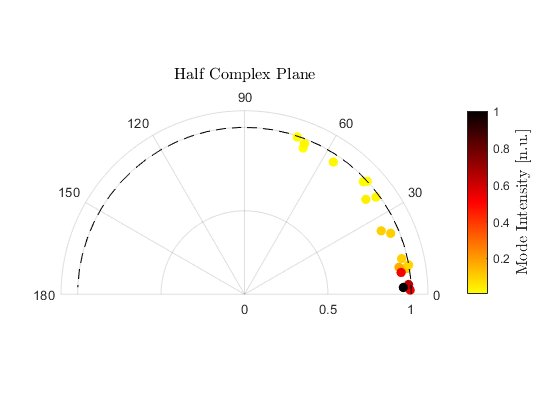

nyqPlot(dmd, norms, freqs, mags, lambda);

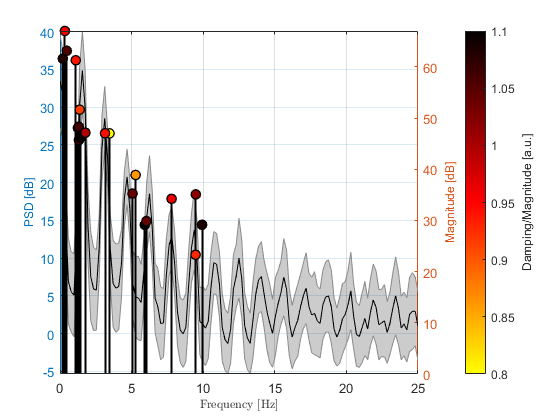

powSpect(dmd, X, freqs, norms, mags, fs);

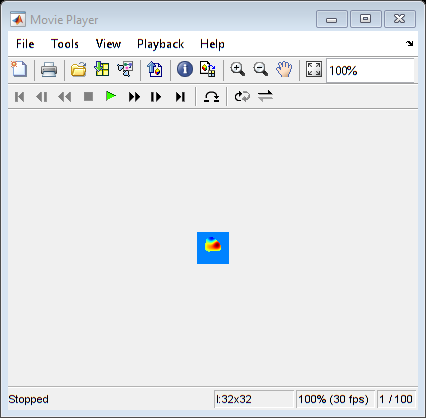

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),32,32,[]));

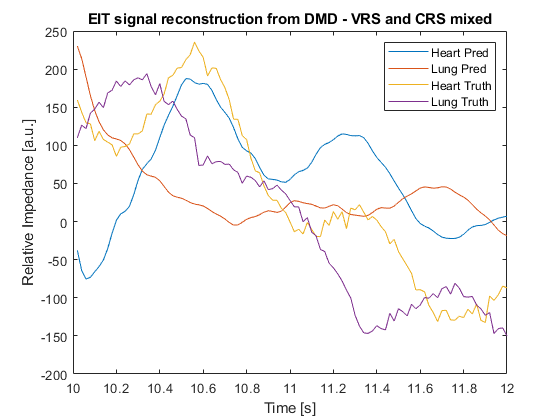

img = real(reshape(Xtotal,32,32,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Compressed Multi-Resolution DMD

% Compressed Multi-Resolution DMD
% Set desired ranges for frequency, norm (or damping factor), and magnitude
nLevels = 5;
freqLims = [0.1,10];
damLims = [0.9,1];
magLims = [0, 1];

% Compress data
[cX, cY, ~] = compressData(dmd, X, Y, 128, 2);

tic
[lambda, omega, Phi, b] = mrFit(dmd, cX, cY, rank, nLevels, predHor, X, Y);

[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                                                    lambda, omega, Phi, b, ....
                                                                                    magLims, damLims, freqLims);

toc

Elapsed time is 0.096782 seconds.


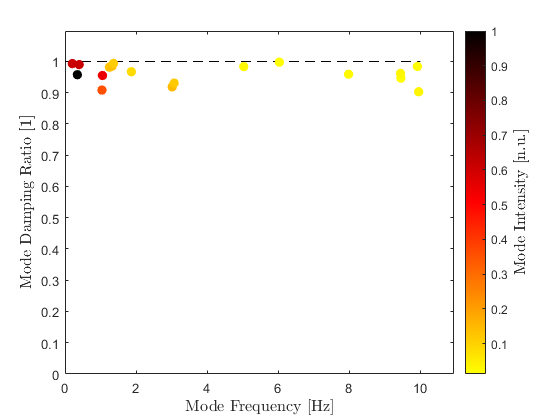

% Visualization
damFreq(dmd, norms, mags, freqs);

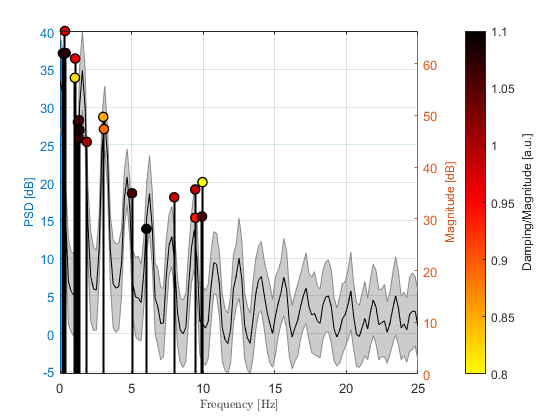

domStruct(dmd, freqs, lambda, Phi, b, predHor);
nyqPlot(dmd, norms, freqs, mags, lambda);
powSpect(dmd, X, freqs, norms, mags, fs);

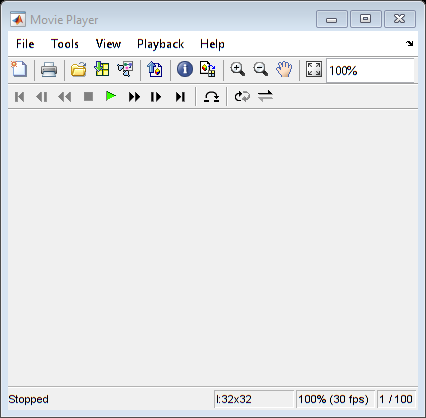

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),32,32,[]));

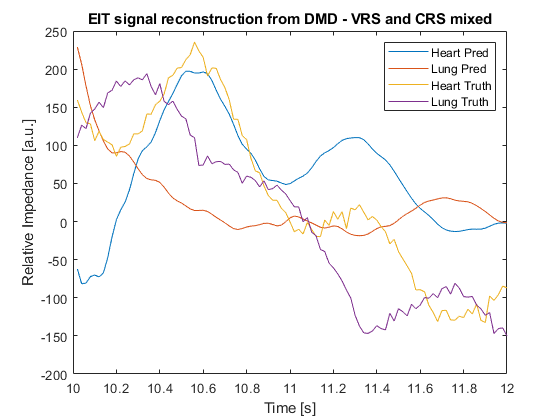

img = real(reshape(Xtotal,32,32,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");